tb = readmatrix('output.txt')

tb =          0         0    0.0011    0.1788
    1.0000         0    0.0029    0.1324
    2.0000         0    0.0128    0.0869
    3.0000         0    0.0741    0.0554
    4.0000         0    0.3984    0.0413
    5.0000         0    0.8995    0.1884
    6.0000         0    0.9728    0.4420
    7.0000         0    0.9838    0.6344
    8.0000         0    0.9651    0.7489
    9.0000         0    0.8698    0.7642


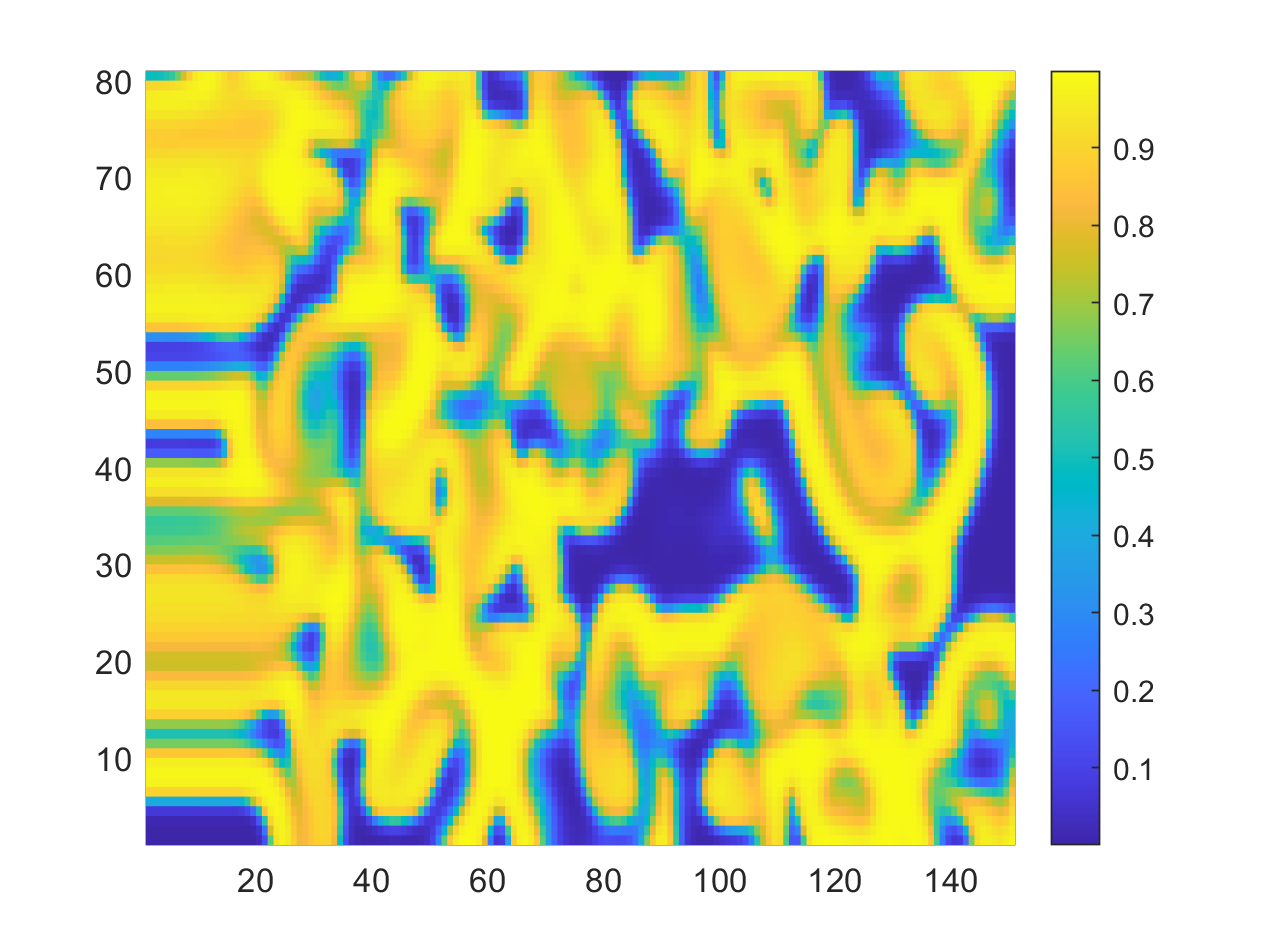

fname2 = '4';
Nx = 81;
x = tb(:,1);
y = tb(:,2);
u = tb(:,3);
v = tb(:,4);

u_mod = reshape(u,Nx,[]);
v_mod = reshape(v,Nx,[]);
fig = figure;
h = pcolor(u_mod);
set(h, 'EdgeColor', 'none');
colorbar

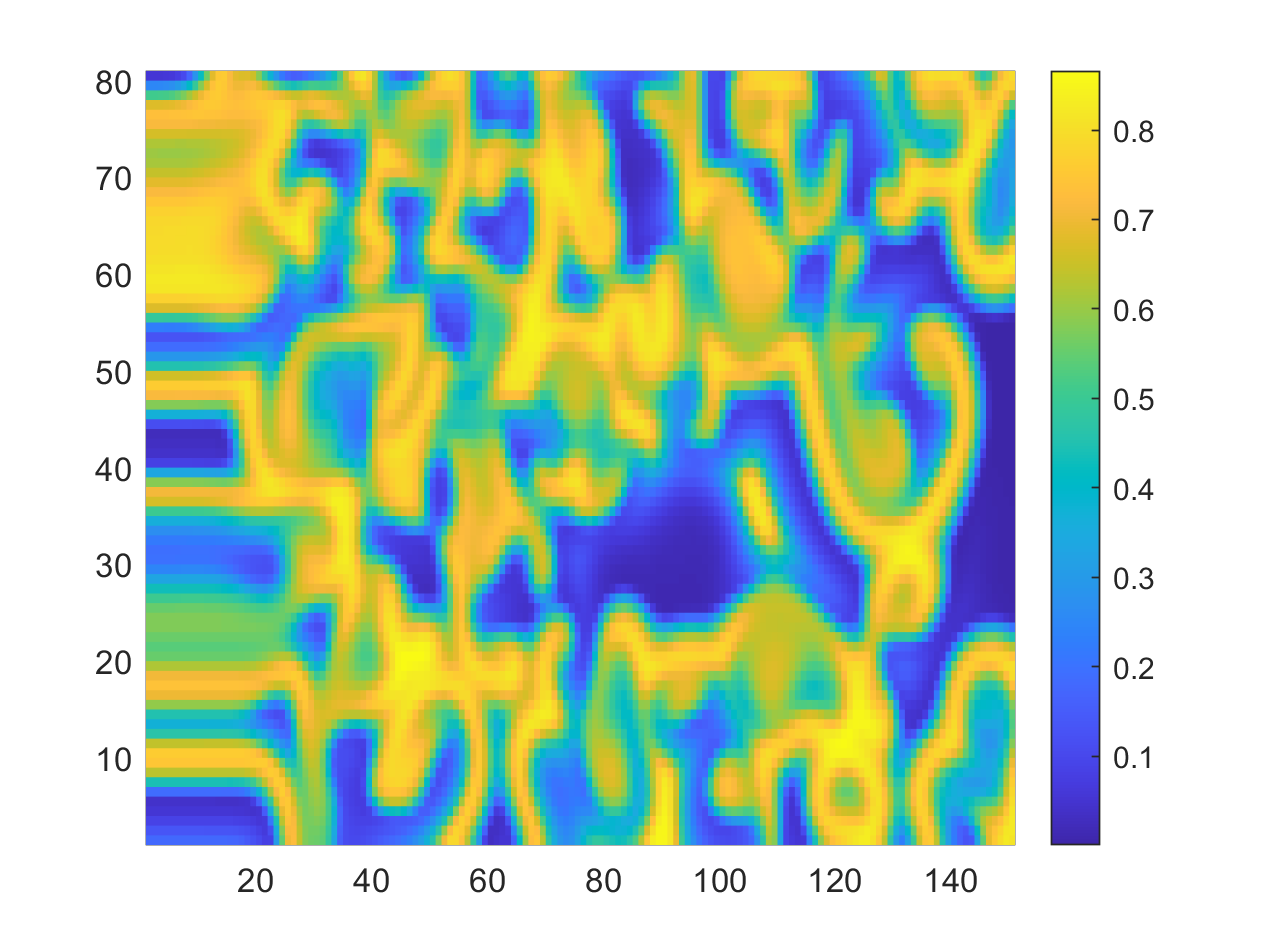

% saveas(fig, ['test' fname2 '_U.png']);

fig2 = figure;
h = pcolor(v_mod);
set(h, 'EdgeColor', 'none');
colorbar

% saveas(fig2, ['test' fname2 '_V.png']);

laptop_threads = [1,2,4,8,12];
laptop_test2_time_omp = [127.760, 87.20, 74.607, 49.883, nan];
laptop_test2_time_mpi = [nan, 77.347, 63.243, 73.602, 92.048];

laptop_test4_time_omp = [24.584, 13.516, 11.150, 10.090, 63.914];
laptop_test4_time_mpi = [nan, 15.667, 11.512, 11.763, 11.884];

typhoon_threads = [1,2,4,8,12,16,20,24,32,40,48,56,64];
typhoon_test2_time_omp = [71.175, 32.687, 18.058, 11.133, 8.441, 7.169...
                          6.543, 6.107, 6.209, 6.125, nan, nan, nan];
typhoon_test2_time_mpi = [nan, 60.763, 31.038, 17.850, 13.664, 11.113,...
                          10.262, 9.988, 8.485, 8.460, 10.531, 11.027, 13.333];

typhoon_test4_time_omp = [11.871, 6.477, 3.693, 2.390, 2.029, 1.783, 1.704...
                          1.852, 1.846, 2.072, nan, nan, nan];
typhoon_test4_time_mpi = [nan, 11.195, 6.564, 4.901, 4.207, 3.714, 3.973,...
                          3.906, 3.546, 3.832, 4.345, 4.126, 3.830];


fig3 = figure;
subplot(2,2,1)
grid on
hold on
plot(laptop_threads, laptop_test2_time_omp, 'x-');
plot(laptop_threads, laptop_test2_time_mpi, 'x-');
legend(["OMP 1(b)", "MPI 1(b)"], 'location', 'best');
title("Laptop Test2");

subplot(2,2,2)
% fig4 = figure;
grid on
hold on
plot(laptop_threads, laptop_test4_time_omp, 'x-');
plot(laptop_threads, laptop_test4_time_mpi, 'x-');
legend(["OMP 1(d)", "MPI 1(d)"], 'location', 'best');
title("Laptop Test4");

subplot(2,2,3)
% fig5 = figure;
grid on
hold on
plot(typhoon_threads, typhoon_test2_time_omp, 'x-');
plot(typhoon_threads, typhoon_test2_time_mpi, 'x-');
legend(["OMP 1(b)", "MPI 1(b)"], 'location', 'best');
title("Typhoon Test2");

subplot(2,2,4)
% fig6 = figure;
grid on
hold on
plot(typhoon_threads, typhoon_test4_time_omp, 'x-');
plot(typhoon_threads, typhoon_test4_time_mpi, 'x-');
legend(["OMP 1(d)", "MPI 1(d)"], 'location', 'best');
title("Typhoon Test4");
saveas(fig3, "Performance_curves.png");


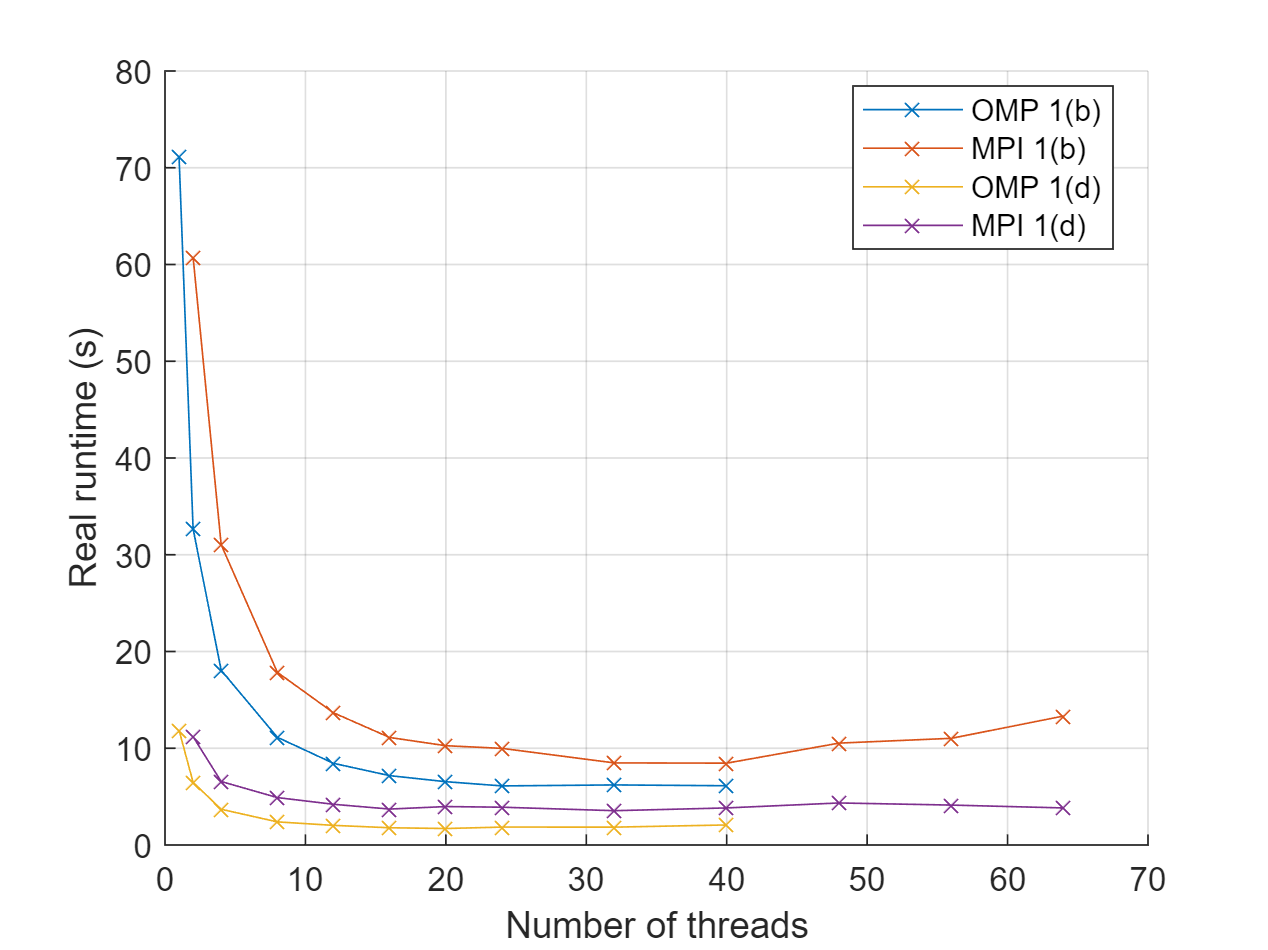

fig5 = figure;
grid on
hold on
plot(typhoon_threads, typhoon_test2_time_omp, 'x-');
plot(typhoon_threads, typhoon_test2_time_mpi, 'x-');
plot(typhoon_threads, typhoon_test4_time_omp, 'x-');
plot(typhoon_threads, typhoon_test4_time_mpi, 'x-');
legend(["OMP 1(b)", "MPI 1(b)", "OMP 1(d)", "MPI 1(d)"], 'location', 'best');
xlabel("Number of threads");
ylabel("Real runtime (s)");

% saveas(fig5, "test2_typhoon.png");

% fig6 = figure;
% grid on
% hold on
% plot(typhoon_threads, typhoon_test4_time_omp, 'x-');
% plot(typhoon_threads, typhoon_test4_time_mpi, 'x-');
% legend(["OMP 1(d)", "MPI 1(d)"], 'location', 'best');
% xlabel("Number of threads");
% ylabel("Real runtime (s)");
% saveas(fig6, "test4_typhoon.png");